## 6.1


% Planeamento

% 1- Ter alfabeto
    alfabeto_nums = ['a':'z' 'A':'Z' '0':'9']

alfabeto_nums = 'abcdefghijklmnopqrstuvwxyzABCDEFGHIJKLMNOPQRSTUVWXYZ0123456789'

%
% 2- Determinar tamanho da chave
     imin = 4;
     imax = 12;
    % tamanho = randi([imin imax])
%
% 3- gerar 1 chave
   % gerar cada um dos caracteres
   %  rand_idx = randi(length(alfabeto), 1,tamanho);
   %   rand_key = alfabeto(rand_idx);
   %   fprintf(1,"Chave = %s\n",rand_key);

NC = 1e2

NC = 100

randKeys(NC, imin, imax, alfabeto_nums)

ans = 1×100 cell array
    {'whpy8u'}    {'VIrDP640V'}    {'OKAS7'}    {'qJVo'}    {'n8sQwxxI'}    {'p1e1ZC'}    {'Vk72LblsHR'}    {'wJup'}    {'X5Z4J6cSN'}    {'R3e6M'}    {'Ifpv1g'}    {'rhZVVfSCfK'}    {'j18fyVs2j6H'}    {'ZyqVZqUMzOC'}    {'gjIzunVT0j'}    {'fGkNj5U5Zau'}    {'h08GIH'}    {'IlHoBp'}    {'dl3WiwHiIAx'}    {'00WjMkCc0'}    {'5TyML38J'}    {'27U5P6i'}    {'DCUEjPYN'}    {'qKtZuI4'}    {'QR67'}    {'1kuVcc9nPCq'}    {'51giPz'}    {'aWaQ37ox'}    {'Y2kHbK3Dq'}    {'14n6H'}    {'79wGOjfpiSa'}    {'8KFjPRKLb'}    {'PaOiOuOLY2'}    {'IRIzkohmd3'}    {'hmyTxrgXFL'}    {'A0yz'}    {'o2bTrL'}    {'6pzbDNNFzJ'}    {'UhP0rVDkV'}    {'odgXyJjF63zC'}    {'gAt9Ay'}    {'kzFrOMR'}    {'EtO8Wy'}    {'IPWzRria'}    {'vXBi'}    {'h0Bg67'}    {'02MCQt'}    {'vISwkOuG'}    {'Q5fFKTkIQ'}    {'Rx7L'}    {'wckyohA'}    {'HFsJtcDRRKxc'}    {'rtFvWVqwq'}    {'C4WNDs3P'}    {'mZQTUGcCQX'}    {'fQY6g5Ts'}    {'QxU629oj'}    {'eFe4FiJ'}    {'Xtrx'}    {'OyF5AzF'}    {'5COVvNkqnzr'}    {'UoeeoY5

keys = randKeys(NC, imin, imax)

keys = 1×100 cell array
    {'jsCfCAFioP'}    {'goIAutT'}    {'xamIAvNnn'}    {'YLhGMrql'}    {'bgPhY'}    {'Alzwa'}    {'NqsIF'}    {'PJYUFYy'}    {'tPvnnOKws'}    {'MpnyjyWBETw'}    {'NREIxg'}    {'CBCptupa'}    {'jNPqum'}    {'WQvLbRWb'}    {'QdrkTNoy'}    {'rpSDteyIvH'}    {'igVLIRFocSdz'}    {'LsLBjgHgO'}    {'CGKSC'}    {'dYScIUkgGbrV'}    {'CSvv'}    {'qhxYRooBK'}    {'FFSotSk'}    {'TONEq'}    {'MTtfMiNJl'}    {'FSbDerNC'}    {'Tdrbo'}    {'OeleO'}    {'qGUnukQcx'}    {'tiEChY'}    {'feBqyfYNUI'}    {'lQnMuaiiytk'}    {'JIlsM'}    {'QupS'}    {'sBqzxPCvl'}    {'PWnRa'}    {'SqCPa'}    {'waxCmE'}    {'teMKsNKFq'}    {'liBqFzDhy'}    {'xKmmgCC'}    {'qiSs'}    {'rUgRomsi'}    {'dMNdPebUMfE'}    {'ORSywGV'}    {'TiUvHgSVii'}    {'CgRBPelSGK'}    {'WOIeQ'}    {'iVFlJKXcfHOc'}    {'wNskVfDmLG'}    {'OrhGoaYf'}    {'fYhKgL'}    {'MmlLOvQdjoXi'}    {'rQiBtWX'}    {'ttIgvgAVKBGg'}    {'vKKFN'}    {'uZFWTeoch'}    {'uKeIuwPpuT'}    {'OqainytbZfRW'}    {'ijsJWiWQiDd'}    {'mUHuvhbeiYiL'}

## 6.2

% INPUT: Temos lista de chaves

funcoes = { 'djb2', 'sdbm'}

funcoes = 1×2 cell array
    {'djb2'}    {'sdbm'}



hashcodes= zeros(length(keys),1);
% 1- iterar toda a lista
for i = 1:NC
    for M = [5e5 1e6 2e6]
        for j = 1:2
        % 2- aplicar função de hash a cada chave
            hc = string2hash(keys{i}, funcoes{j});
        
        % 3- Transformar hashcode para intervalo 0: M - 1          M = (5e5, ...
            hc = mod(hc, M);
        
        % 4- guardar hashcodes num a-rray de NUM_CHAVES
            hashcodes(i, j) = hc;
        end
    end
end
hashcodes

hashcodes =      1235533      383846
      258165      108805
      285210     1540984
     1939923      183626
      164688     1578480
     1255221     1143402
      842711     1032202
     1865136     1209862
      224961     1013561
     1044121      291134


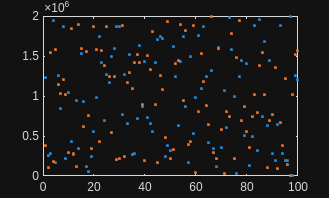

plot(1:NC,hashcodes,'.')

## 6.3

n = 8000;
BF = inicializar(n);
k = 3;

elemento = 'Aveiro';
BF = adicionar(elemento,BF,k)

Aveiro1
Aveiro12
Aveiro123


BF = 1×8000 uint8 row vector
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


find(BF == 1)

ans =         3211        6427        6436


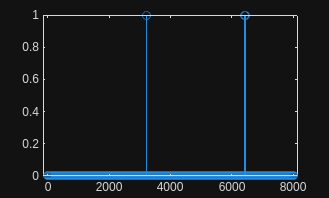

sum(BF);
stem(BF);



x = 'Aveiro'

x = 'Aveiro'

r = pertence(x,BF,k)

Aveiro1
Aveiro12
Aveiro123


r = logical
   1
